# 

## MATLAB Fundamentals: Tutorial 01, Exercise 02

### August 2023

# 2. Data Types 

In this exercise you will learn how to handle data types in MATLAB. Table 1 below contains an excerpt of the data of attendants at a party, and Table 2 the data types used for each entry. There are different ways to arrange this data in MATLAB. Save your results analogue to exercise one.

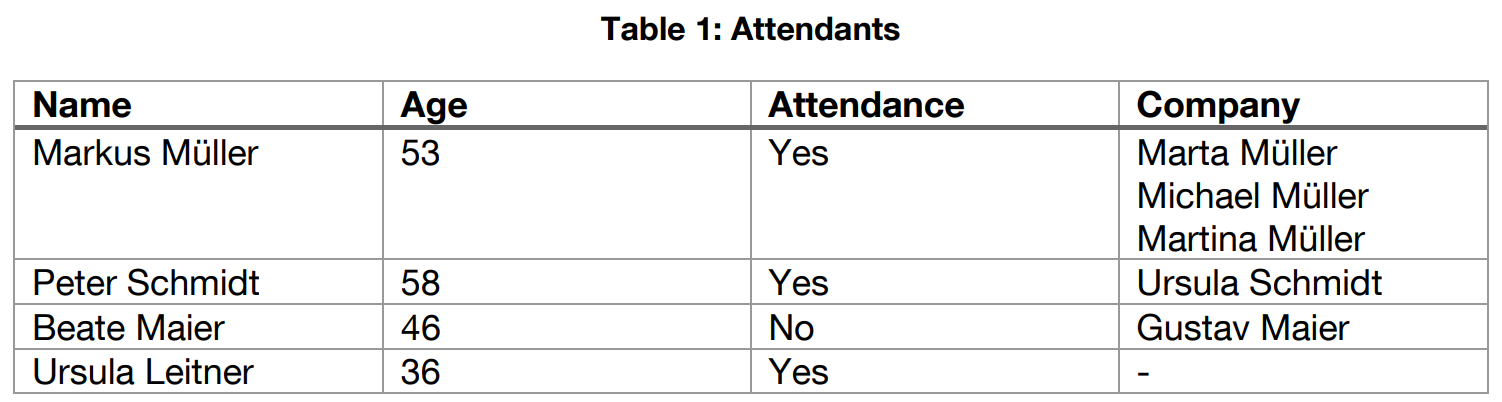

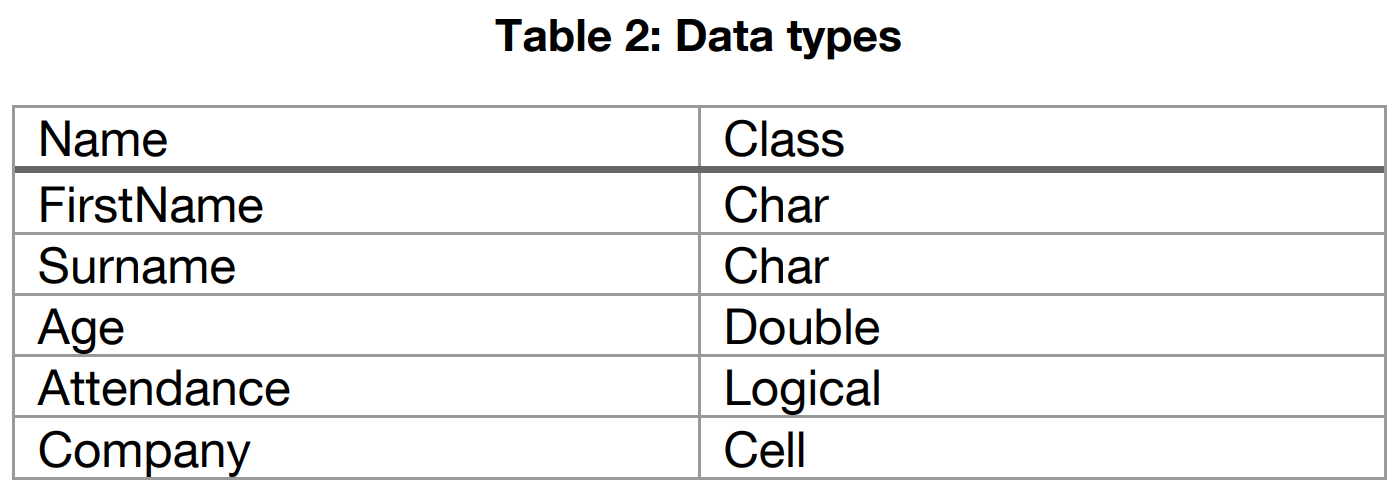

**Exercise**

(1)    Create a cell array called “CellData“ containing all data from Table 1, such that each row acts as a container for the data types in Table 2. Arrange the company cell array such that the first column represents the surname and the second column the first name. 

cellData = {
    % Markus Müller
    'Markus Müller', 'Markus', 'Müller', 53, true, {'Müller', 'Marta'; 'Müller', 'Michael'; 'Müller', 'Martina'};

    % Peter Schmidt
    'Peter Schmidt', 'Peter', 'Schmidt', 58, true, {'Schmidt', 'Ursula'};

    % Beate Maier
    'Beate Maier', 'Beate', 'Maier', 46, false, {'Maier', 'Gustav'};

    % Ursula Leitner
    'Ursula Leitner', 'Ursula', 'Leitner', 36, true, {}
};

### *Hint:* If it is more convenient for you, you can use the variable editor to fill in the information after finishing the first entry. Open the variable editor interactively or by entering the openvar command.

(2)    Save the `CellData` variable in a file called `CellData.mat`.

save('CellData.mat','CellData')

(3)    Use the `struct` command to create a structure array called “StructData“ containing all data. Use the Names from Table 2 as field names. 

structData = struct(...
    'Name', {'Markus Müller', 'Peter Schmidt', 'Beate Maier', 'Ursula Leitner'}, ...
    'FirstName', {'Markus', 'Peter', 'Beate', 'Ursula'}, ...
    'Surname', {'Müller', 'Schmidt', 'Maier', 'Leitner'}, ...
    'Age', {53, 58, 46, 36}, ...
    'Attendance', {true, true, false, true}, ...
    'Company', { ...
        {'Müller', 'Marta'; 'Müller', 'Michael'; 'Müller', 'Martina'}, ...
        {'Schmidt', 'Ursula'}, ...
        {'Maier', 'Gustav'}, ...
        {} ...
    } ...
)

(4)    Extract Mr. Müller’s data and save each data field to a variable which is called as in Table 2. Check all variable in your workspace using the `whos` command.

name = StructData(1).Name;
firstName = StructData(1).FirstName;
surName = StructData(1).Surname;
age = StructData(1).Age;
attendance = StructData(1).Attendance;
company = StructData(1).Company;

(5)    Create a table containing the same data as in the structure. Use the documentation on tables to find the most efficient way.

tableData = struct2table(StructData)

(6)    Find the mean age of all attending guests.

attendanceGuests = tableData(tableData.Attendance == true,:);
meanAge = mean(attendanceGuests.age);

### Hint: use logical indexing to extract a structure array containing attending guests.

(7)    Save the expression created in step (6) to a function handle called `getMean(data)`.

getMean = @(data) mean(data.Age(data.Attendance == true));

Technische Universität München – Lehrstuhl für Flugsystemdynamik – MATLAB Fundamentals: Tutorial 01 – August 2023